# Ideal Smapling and Reconstruction

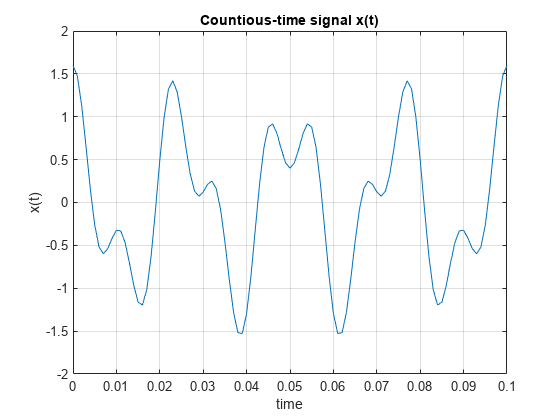

t = 0:0.001:0.1;
f1 = 40;
f2 = 90;
func = @(t)cos(2.*pi.*f1.*t) + 0.6.*cos(2.*pi.*f2.*t);

x = func(t);
%plot
figure;
plot(t , x);
xlabel("time");ylabel("x(t)");title("Countious-time signal x(t)");grid("on");

## sampling

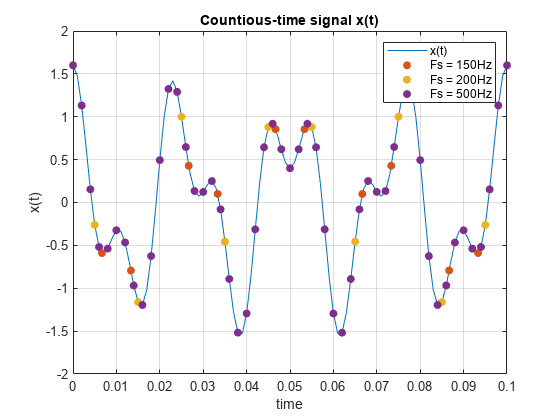

Fs = [150 , 200, 500];
Ts = 1./Fs;

t1 = 0:Ts(1):0.1;
t2 = 0:Ts(2):0.1;
t3 = 0:Ts(3):0.1;

figure;
plot(t , x);hold on;
scatter(t1,func(t1) ,"filled");
scatter(t2 , func(t2), "filled");
scatter(t3 , func(t3), "filled");
legend(["x(t)" , "Fs = 150Hz" , "Fs = 200Hz", "Fs = 500Hz"])
xlabel("time");ylabel("x(t)");title("Countious-time signal x(t)");grid("on");

## Reconstruction:

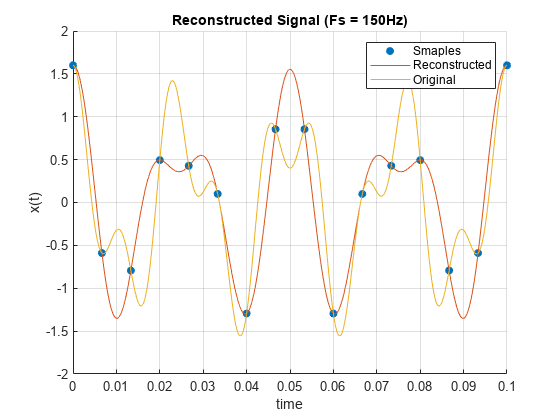

t = linspace(0,0.1, 50000);
x = func(t);

%Fs = 150Hz
[Ts_grid, T_grid] = ndgrid(t , t1);
x1 = func(t1);
x_r1 = sinc((Ts_grid-T_grid)./Ts(1))* x1(:);


figure;
scatter(t1,x1 ,"filled"); hold on;
plot(t , x_r1);
plot(t , x);
legend(["Smaples", "Reconstructed", "Original"]);
xlabel("time");ylabel("x(t)");title("Reconstructed Signal (Fs = 150Hz)");grid("on");

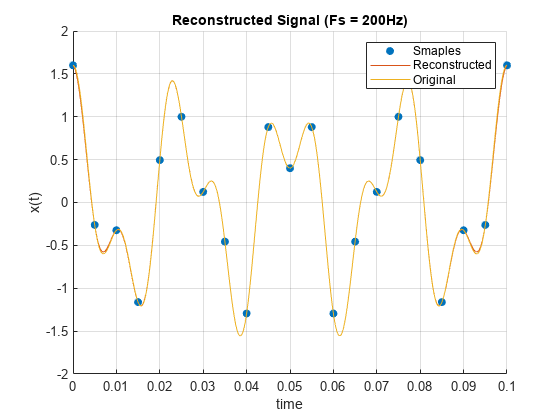




%Fs = 200Hz
[Ts_grid, T_grid] = ndgrid(t , t2);
x2 = func(t2);
x_r2 = sinc((Ts_grid-T_grid)./Ts(2))* x2(:);


figure;
scatter(t2,x2 ,"filled"); hold on;
plot(t , x_r2);
plot(t , x);
legend(["Smaples", "Reconstructed", "Original"]);
xlabel("time");ylabel("x(t)");title("Reconstructed Signal (Fs = 200Hz)");grid("on");

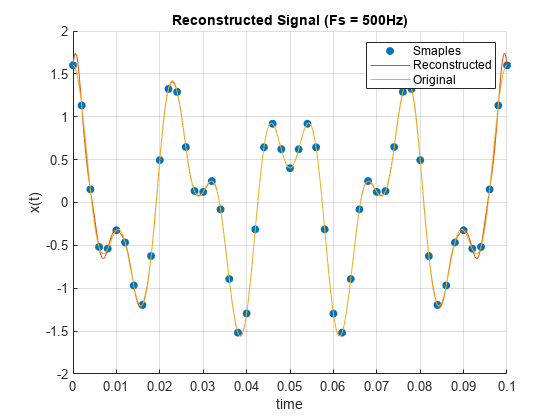

err =     0.3762    0.0001    0.0014





%Fs = 500Hz
[Ts_grid, T_grid] = ndgrid(t , t3);
x3 = func(t3);
x_r3 = sinc((Ts_grid-T_grid)./Ts(3))* x3(:);


figure;
scatter(t3,x3 ,"filled"); hold on;
plot(t , x_r3);
plot(t , x);
legend(["Smaples", "Reconstructed", "Original"]);
xlabel("time");ylabel("x(t)");title("Reconstructed Signal (Fs = 500Hz)");grid("on");

# Aliasing in the Frequency Domain

The maximum frequency of the signal is: $f_M = 160 \, \text{Hz}
$. So, the Nyquist frequency is: $f_s = 2 f_M = 320 \, \text{Hz}
$

The frequency given in part **b** is not high enough and resulting aliasing.

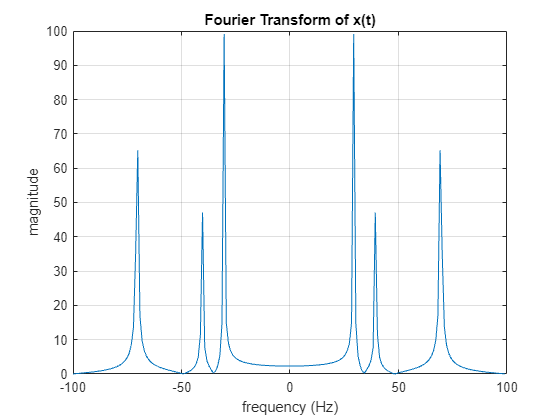

Fs = 200;
t = 0:1/Fs:1;
N = length(t);
cos_func = @(t , f, a) a.*cos(2.*pi.*f.*t);

f = [30, 70, 160];
x = cos_func(t, f(1) , 1) + cos_func(t , f(2) , 0.8) + cos_func(t , f(3) , 0.5);

x1 = cos_func(t, f(1) , 1);
x2 = cos_func(t , f(2) , 0.8);
x3 = cos_func(t , f(3) , 0.5);

f_axis = linspace(-Fs/2, Fs/2-Fs/N, N);
Xs = fftshift(fft(x));

Xs_1 = fftshift(fft(x1));
Xs_2 = fftshift(fft(x2));
Xs_3 = fftshift(fft(x3));
figure;
plot(f_axis, abs(Xs));
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier Transform of x(t)");grid on;

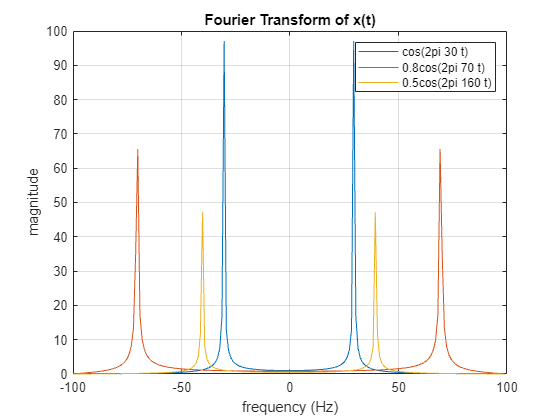


figure;
plot(f_axis , abs(Xs_1));hold on;
plot(f_axis , abs(Xs_2));
plot(f_axis , abs(Xs_3));
legend(["cos(2pi 30 t)" , "0.8cos(2pi 70 t)", "0.5cos(2pi 160 t)"])
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier Transform of x(t)");grid on;

For $f_s = 400 \, \text{Hz}
$:

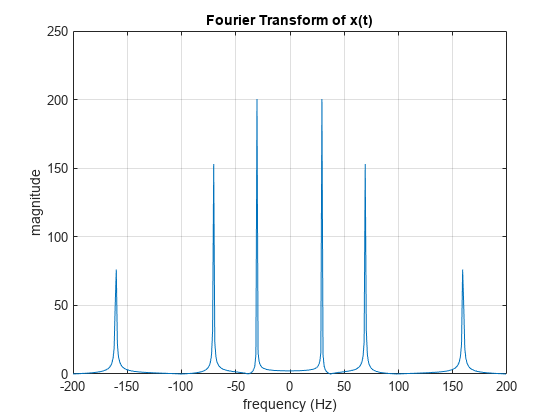

Fs = 400;
t = 0:1/Fs:1;
N = length(t);
cos_func = @(t , f, a) a.*cos(2.*pi.*f.*t);

f = [30, 70, 160];
x = cos_func(t, f(1) , 1) + cos_func(t , f(2) , 0.8) + cos_func(t , f(3) , 0.5);

x1 = cos_func(t, f(1) , 1);
x2 = cos_func(t , f(2) , 0.8);
x3 = cos_func(t , f(3) , 0.5);

f_axis = linspace(-Fs/2, Fs/2-Fs/N, N);
Xs = fftshift(fft(x));

Xs_1 = fftshift(fft(x1));
Xs_2 = fftshift(fft(x2));
Xs_3 = fftshift(fft(x3));
figure;
plot(f_axis, abs(Xs));
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier Transform of x(t)");grid on;

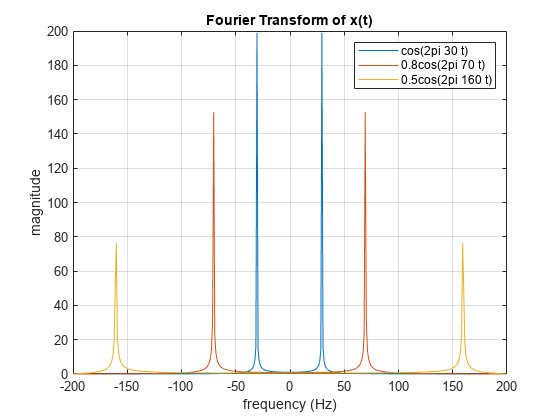


figure;
plot(f_axis , abs(Xs_1));hold on;
plot(f_axis , abs(Xs_2));
plot(f_axis , abs(Xs_3));
legend(["cos(2pi 30 t)" , "0.8cos(2pi 70 t)", "0.5cos(2pi 160 t)"])
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier Transform of x(t)");grid on;

# **Zero-Order Hold**

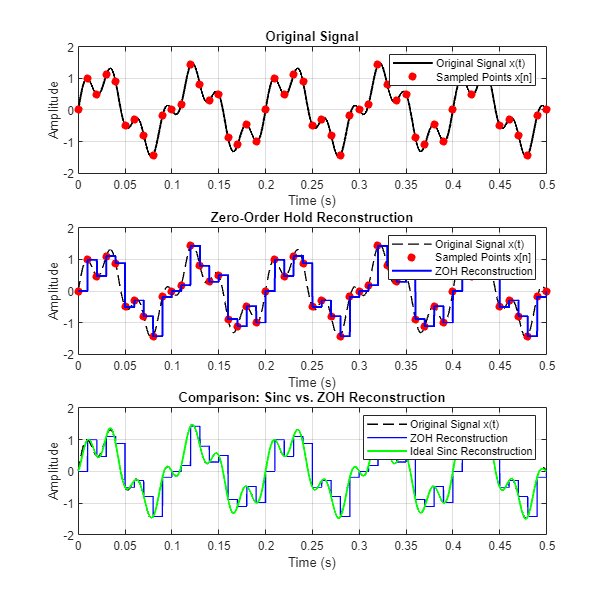

Fs = 100;                 
Ts = 1/Fs;                
t = 0:0.0001:0.5;         
t_n = 0:Ts:0.5;           

x_t = sin(2*pi*10*t) + 0.5*sin(2*pi*35*t);
x_n = sin(2*pi*10*t_n) + 0.5*sin(2*pi*35*t_n);

figure('Name', 'Sampling and Reconstruction', 'Position', [100, 100, 800, 800]);

subplot(3,1,1);
plot(t, x_t, 'k', 'LineWidth', 1.5); hold on;
scatter(t_n, x_n, 'r', 'filled', 'LineWidth', 1.5);
title('Original Signal');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Original Signal x(t)', 'Sampled Points x[n]');
grid on;

x_zoh = interp1(t_n, x_n, t, 'previous'); 

subplot(3,1,2);
plot(t, x_t, 'k--', 'LineWidth', 1); hold on;
scatter(t_n, x_n, 'r', 'filled', 'LineWidth', 1.5);
plot(t, x_zoh, 'b', 'LineWidth', 1.5);
title('Zero-Order Hold Reconstruction');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Original Signal x(t)', 'Sampled Points x[n]', 'ZOH Reconstruction');
grid on;

[Ts_grid, T_grid] = ndgrid(t, t_n);
x_sinc = sinc((Ts_grid - T_grid) / Ts) * x_n(:);

subplot(3,1,3);
plot(t, x_t, 'k--', 'LineWidth', 1); hold on;
plot(t, x_zoh, 'b', 'LineWidth', 1);
plot(t, x_sinc, 'g', 'LineWidth', 1.5);
title('Comparison: Sinc vs. ZOH Reconstruction');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Original Signal x(t)', 'ZOH Reconstruction', 'Ideal Sinc Reconstruction');
grid on;


error_zoh = mean((x_t - x_zoh).^2)

error_zoh = 0.2229

error_sinc = mean((x_t - x_sinc').^2)

error_sinc = 6.3245e-04

# **Digital processing**

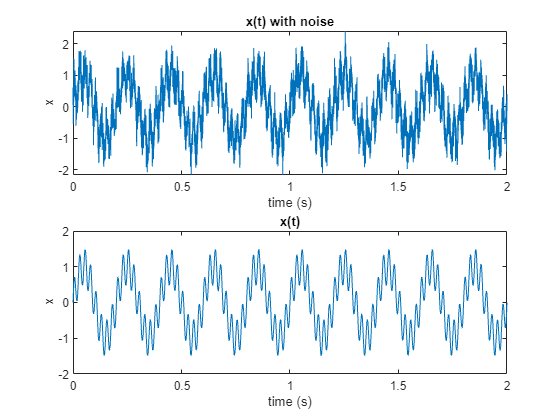

Fs = 200;

func = @(t) sin(2.*pi.*5.*t) + 0.5.*sin(2.*pi.*40.*t) ;

t = linspace(0,2,5000);
figure;
subplot(2,1,1);
plot(t, func(t) + 0.3*normrnd(0,1,[1,length(t)]));
xlabel("time (s)");ylabel("x");title("x(t) with noise");
subplot(2,1,2);
plot(t , func(t));
xlabel("time (s)");ylabel("x");title("x(t)");

## sample:

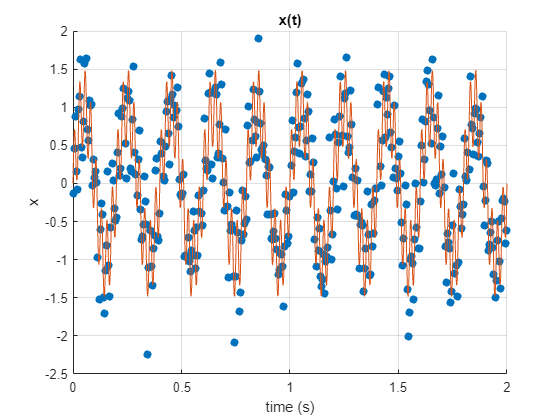

ts = 0:1/Fs:2;
xs = func(ts) + 0.3*normrnd(0,1,[1,length(ts)]);
N = length(ts);

Xs = fft(xs);
f_axis = linspace(-Fs/2, Fs/2-Fs/N, N);


figure;
scatter(ts, xs, "filled");hold on;
plot(t, func(t));
xlabel("time (s)");ylabel("x");title("x(t)"); grid on;

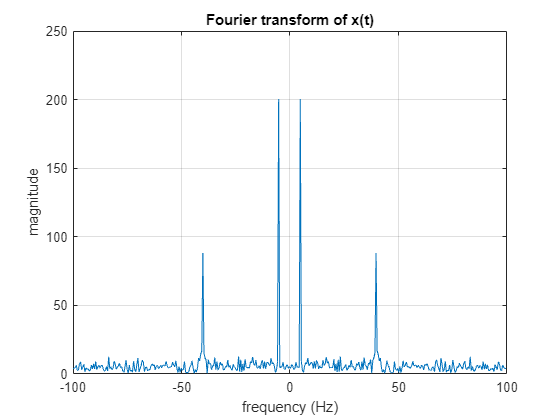


figure;
plot(f_axis, abs(fftshift(Xs)));
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier transform of x(t)"); grid on;

## Moving Average:

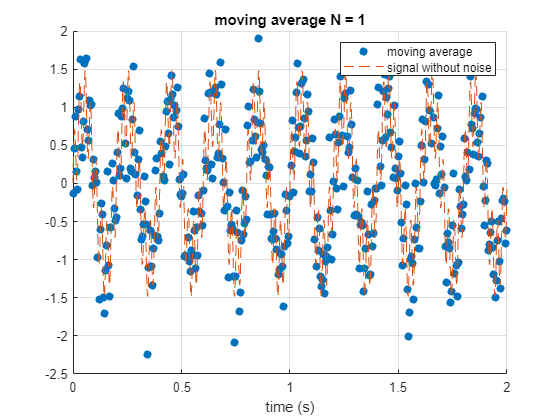

w = 2*pi.*f_axis;
N_avg = 1;

H = (1/N_avg)*(1-exp(-1i*w*N_avg))./(1-exp(-1i*w));
H(1) = 1;          %DC value...

Y = Xs .* H;
y = ifft(Y);

figure;
scatter(ts, real(y) , "filled");hold on;
plot(t, func(t),LineStyle="--");
legend(["moving average","signal without noise"])
xlabel("time (s)");ylabel("");title(sprintf("moving average N = %d" , N_avg)); grid on;

## Reconstruct:

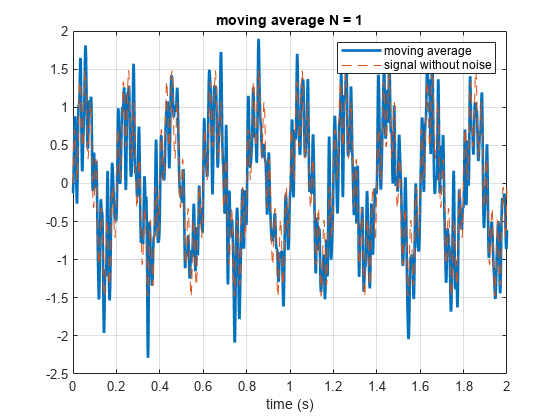

[Ts,T] = ndgrid(ts,t);
y_r = real(y) * sinc((Ts - T).*Fs);

figure;
plot(t, real(y_r) , "LineWidth",2);hold on;
plot(t, func(t),LineStyle="--");
legend(["moving average","signal without noise"])
xlabel("time (s)");ylabel("");title(sprintf("moving average N = %d" , N_avg)); grid on;

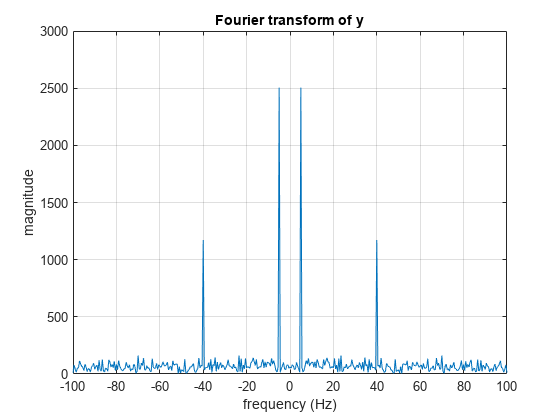


Y_r = fft(y_r);
N_r = length(t);
Fs_r = 2499.5;
fr_axis = linspace(-Fs_r/2, Fs_r/2-Fs_r/N_r, N_r);

figure;
plot(fr_axis, abs(fftshift(Y_r)));
xlabel("frequency (Hz)");ylabel("magnitude");title("Fourier transform of y"); grid on;
xlim([-100,100]);

# Anti-Aliasing Before Sampling

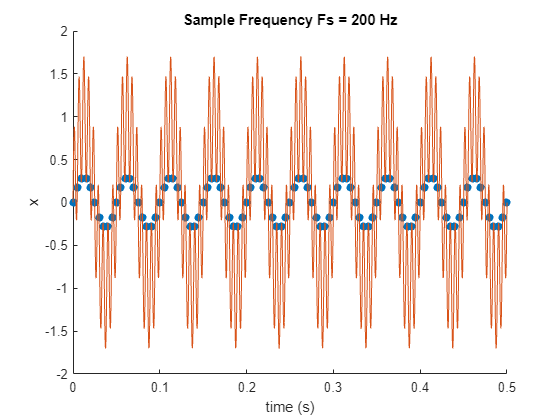

func = @(t) sin(2*pi.*20.*t) +0.7 .* sin(2.*pi*180.*t);

Fs = 200;

%Sampling
t_s = 0:1/Fs:0.5;
t = linspace(0,0.5,5000);
x = func(t);
x_s = func(t_s);

figure;
scatter(t_s , x_s, "filled"); hold on;
plot(t , x );
xlabel("time (s)"); ylabel("x"); title("Sample Frequency Fs = 200 Hz");hold off;

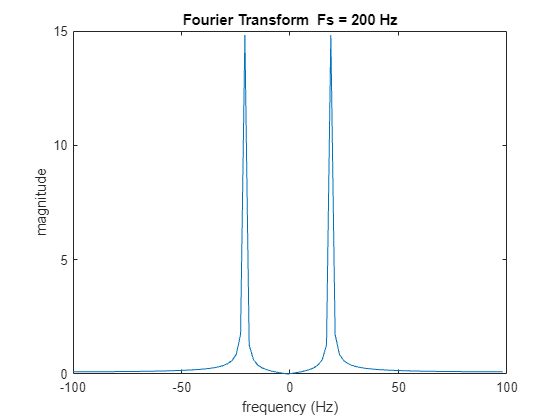


%fft
X_s = fft(x_s);
N = length(t_s);
f_axis = linspace(-Fs/2, Fs/2-Fs/N, N);

figure;
plot(f_axis , abs(fftshift(X_s)));
xlabel("frequency (Hz)");ylabel("magnitude"); title("Fourier Transform  Fs = 200 Hz");

## Anti-Aliasing Filter

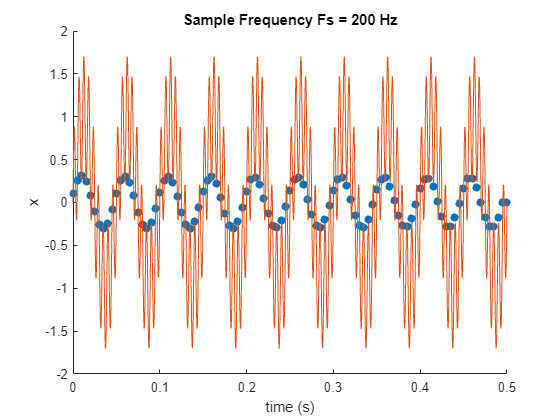

y = lowpass(x,99.5,Fs);
k = (1:100).*50;
y_s = y(k);
y_s(101) = y(5000);
figure;
scatter(t_s , y_s, "filled"); hold on;
plot(t , x );
xlabel("time (s)"); ylabel("x"); title("Sample Frequency Fs = 200 Hz");hold off;

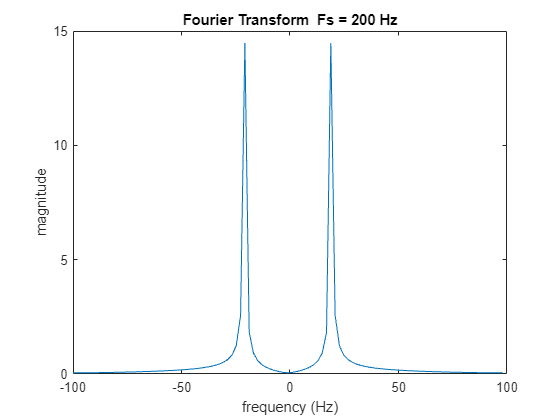


%fft
Y_s = fft(y_s);
N = length(t_s);
f_axis = linspace(-Fs/2, Fs/2-Fs/N, N);

figure;
plot(f_axis , abs(fftshift(Y_s)));
xlabel("frequency (Hz)");ylabel("magnitude"); title("Fourier Transform  Fs = 200 Hz");